# lab 5

## reset

clear, close all

## 1. Завантажте з бібліотеки MATLAB декілька кольорових і чорно-білих зображень різного характеру (що містять великі й дрібні елементи).

colorImage1 = imread('peppers.png');
colorImage2 = imread('autumn.tif');
grayImage1 = imread('cameraman.tif');
grayImage2 = imread('moon.tif');

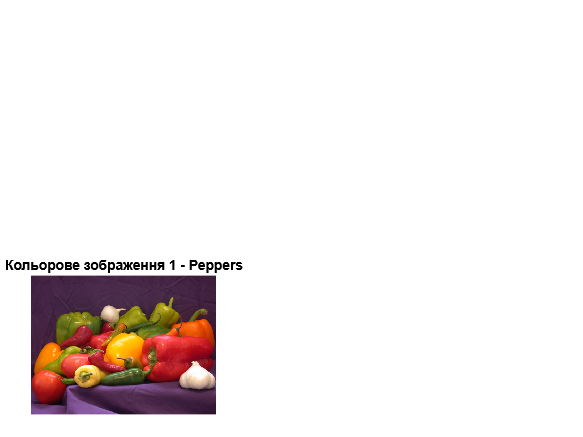

figure, imshow(colorImage1), title('Кольорове зображення 1 - Peppers');

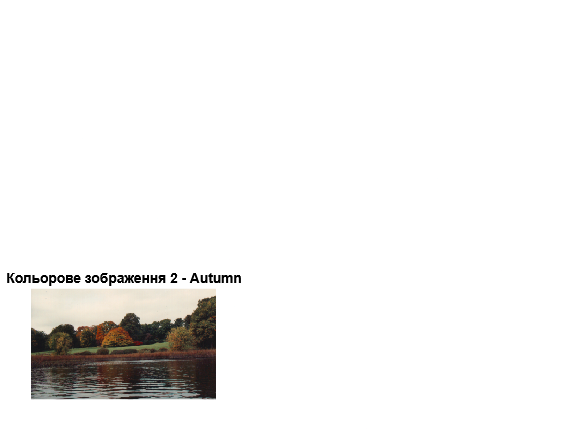

figure, imshow(colorImage2), title('Кольорове зображення 2 - Autumn');

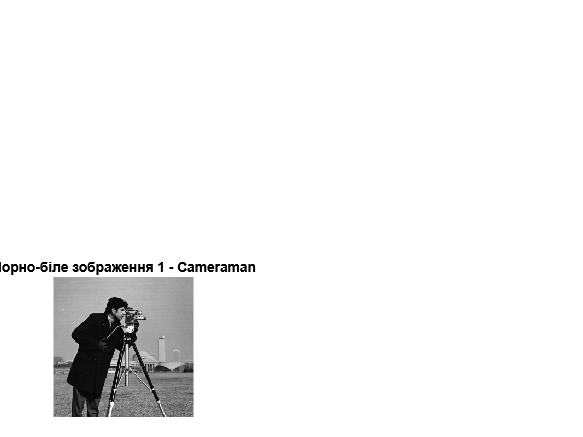

figure, imshow(grayImage1), title('Чорно-біле зображення 1 - Cameraman');

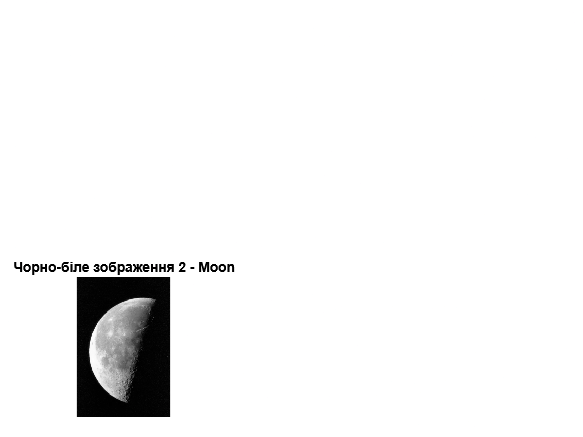

figure, imshow(grayImage2), title('Чорно-біле зображення 2 - Moon');

## 2. З використанням функції rgb2gray перетворіть кольорові зображення в чорно-білі

grayPeppers = rgb2gray(colorImage1);
grayAutumn = rgb2gray(colorImage2);

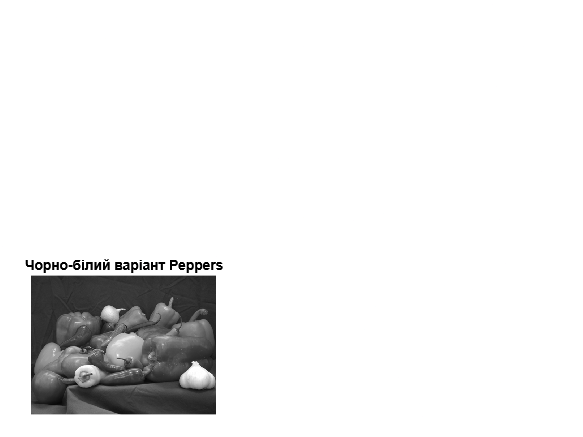

figure, imshow(grayPeppers), title('Чорно-білий варіант Peppers');

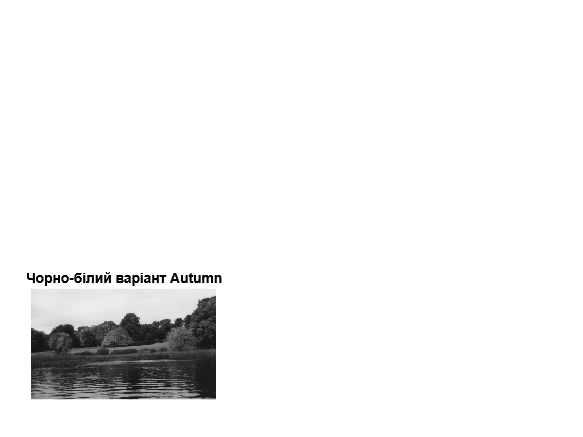

figure, imshow(grayAutumn), title('Чорно-білий варіант Autumn');

## 3.1 З використанням функції dct2 виконайте дискретне косинусне перетворення зображень.

двовимірне дискретне косинусне перетворення (ДКП або DCT)

% Перетворення зображень у формат double перед ДКП
grayPeppersDouble = double(grayPeppers);
grayAutumnDouble = double(grayAutumn);
grayImage1Double = double(grayImage1);
grayImage2Double = double(grayImage2);

% Застосування ДКП до зображень
dctPeppers = dct2(grayPeppersDouble);
dctAutumn = dct2(grayAutumnDouble);
dctCameraman = dct2(grayImage1Double);
dctMoon = dct2(grayImage2Double);

### 3.2 Відобразіть результат ДКП у вигляді зображення з використанням функції imshow. Під час відображенні масиву ДКП-коефіцієнтів використовуйте логарифмічний масштаб.

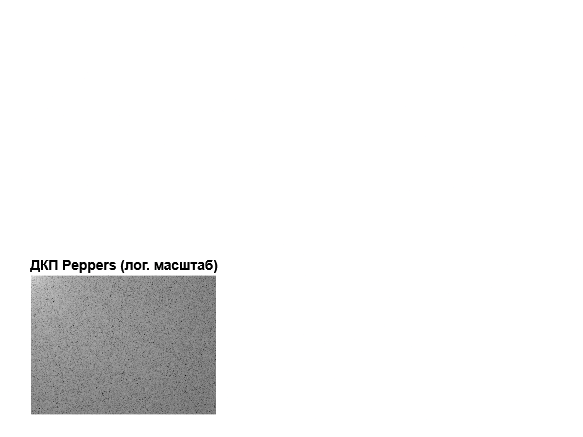

figure, imshow(log(abs(dctPeppers)), []), title('ДКП Peppers (лог. масштаб)');

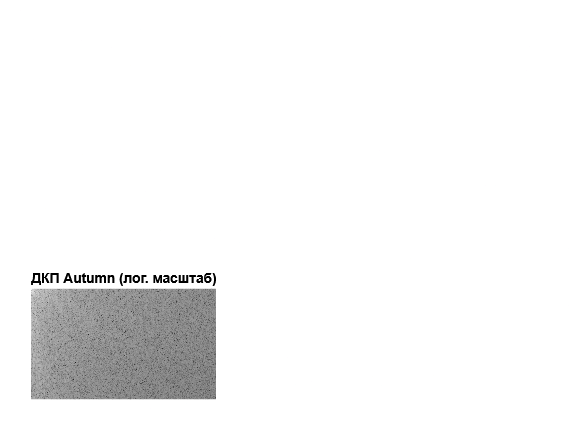

figure, imshow(log(abs(dctAutumn)), []), title('ДКП Autumn (лог. масштаб)');

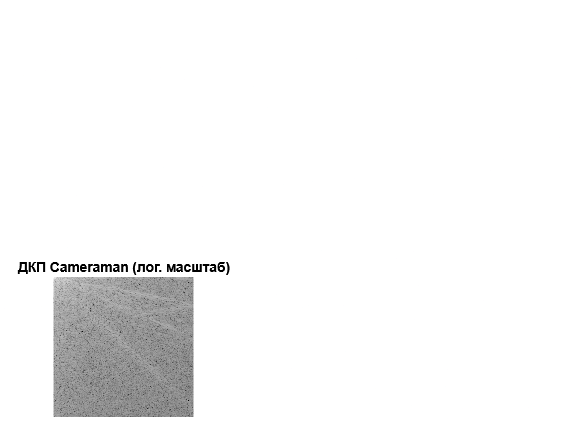

figure, imshow(log(abs(dctCameraman)), []), title('ДКП Cameraman (лог. масштаб)');

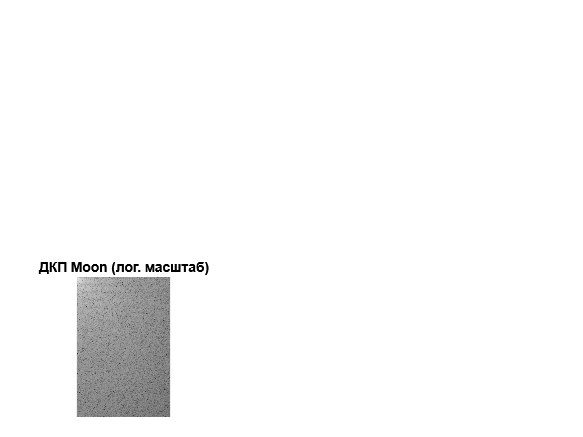

figure, imshow(log(abs(dctMoon)), []), title('ДКП Moon (лог. масштаб)');

## 4. З використанням функції idct2 відновіть зображення за його ДКП-спектру.

reconstructedPeppers = idct2(dctPeppers);
reconstructedAutumn = idct2(dctAutumn);
reconstructedCameraman = idct2(dctCameraman);
reconstructedMoon = idct2(dctMoon);

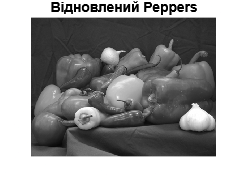

figure, imshow(reconstructedPeppers, [0 255]), title('Відновлений Peppers');

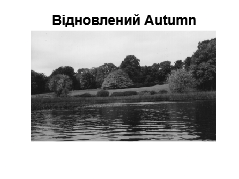

figure, imshow(reconstructedAutumn, [0 255]), title('Відновлений Autumn');

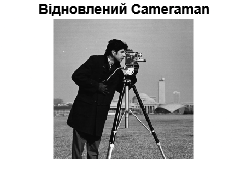

figure, imshow(reconstructedCameraman, [0 255]), title('Відновлений Cameraman');

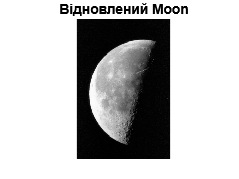

figure, imshow(reconstructedMoon, [0 255]), title('Відновлений Moon');

## 5.1 З використанням процедури целочислового ділення/множення J=N*round(J*N); виконайте квантування результатів ДКП для різних значень кроку квантування N. 

% Квантування ДКП з різними кроками
N_small = 10;
N_medium = 30;
N_large = 80;

% Квантування ДКП для Cameraman
dctCameramanQuantSmall = N_small * round(dctCameraman / N_small);
dctCameramanQuantMedium = N_medium * round(dctCameraman / N_medium);
dctCameramanQuantLarge = N_large * round(dctCameraman / N_large);

### 5.2 Поясніть, як працює ця процедура, і що отримаємо в результаті.

*Пояснення процедури квантування ДКП:*

*Використання формули J = (round(J/N))*N;*

*  1. Ділення кожного коефіцієнта ДКП на крок квантування N. (J/N)*

*  2. Округлення результату до найближчого цілого числа. (round(J/N))*

*  3. Множення округленого результату на N. (N * round(J/N))*

*Результатом є ДКП-коефіцієнти, квантовані з кроком N*

*У результаті цієї операції:*

*Коефіцієнти ДКП округлюються до найближчого значення, кратного N. Коефіцієнти, менші за N/2 за модулем, округлюються до нуля. Чим більше значення N, тим більше коефіцієнтів стають нульовими. Зменшується кількість унікальних значень у масиві ДКП. Збільшується ступінь потенційного стиснення даних*

## 6.1 Відобразіть результати у вигляді зображення ( як і раніше для ДКП –у логарифмічному масштабі). 

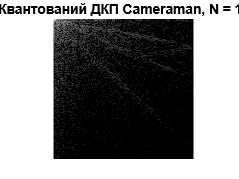

figure, imshow(log(abs(dctCameramanQuantSmall)), []), title(['Квантований ДКП Cameraman, N = ', num2str(N_small)]);

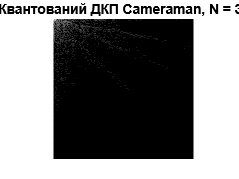

figure, imshow(log(abs(dctCameramanQuantMedium)), []), title(['Квантований ДКП Cameraman, N = ', num2str(N_medium)]);

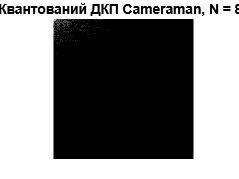

figure, imshow(log(abs(dctCameramanQuantLarge)), []), title(['Квантований ДКП Cameraman, N = ', num2str(N_large)]);

### 6.2 Поясніть вигляд отриманих даних.

*При малому N зберігається більшість коефіцієнтів (видно багато ненульових точок) (нульові точоки == чорні точки на злбражені)*

*При збільшенні N залишаються лише найбільші коефіцієнти (переважно в лівому верхньому куті), що відповідають за низькочастотні компоненти зображення.*

*Кількість ненульових коефіцієнтів різко зменшується зі збільшенням N.*

## 7.1 З використанням функції idct2 відновіть зображення за квантованим ДКП-спектром для різних значень кроку квантування. 

% Відновлення зображень із квантованих ДКП
reconstructedQuantSmall = idct2(dctCameramanQuantSmall);
reconstructedQuantMedium = idct2(dctCameramanQuantMedium);
reconstructedQuantLarge = idct2(dctCameramanQuantLarge);

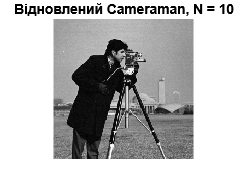

% Відображення відновлених зображень
figure, imshow(reconstructedQuantSmall, [0 255]), title(['Відновлений Cameraman, N = ', num2str(N_small)]);

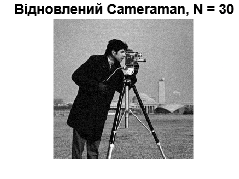

figure, imshow(reconstructedQuantMedium, [0 255]), title(['Відновлений Cameraman, N = ', num2str(N_medium)]);

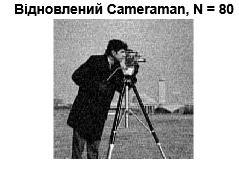

figure, imshow(reconstructedQuantLarge, [0 255]), title(['Відновлений Cameraman, N = ', num2str(N_large)]);

### 7.2 Поясніть отримані результати.

*При малому N (наприклад, 10) якість відновленого зображення майже не відрізняється від оригіналу*

*При середньому N (30) з'являються невеликі артефакти, але зображення все ще впізнаване*

*При великому N (80) якість значно погіршується, з'являються блочні артефакти, втрачаються дрібні деталі, проте основна структура зображення зберігається*

## 8. Поясніть, яка мета досягається квантуванням коефіцієнтів ДКП.

*Основною метою квантування коефіцієнтів ДКП є*

***зменшення обсягу даних****, необхідних для*

*представлення зображення, тобто стиснення. *

*Квантування зменшує точність представлення,*

*але завдяки властивостям ДКП (концентрація енергії в низькочастотних коефіцієнтах)*

*і особливостям людського зору (менша чутливість до високочастотних компонентів)*

*можна досягти значного стиснення з прийнятною візуальною якістю.*

## 9. Чи можливо добитися аналогічної мети й результату, квантуючи вихідне зображення, а не коефіцієнти його ДКП? Перевірте це на практиці, квантуючи з використанням процедури I = (round(J/n))*n вихідні зображення й відобразіть отриманий результат. Поясніть результат.

## 9.2 квантування

% Квантування вихідного зображення з різними кроками
N_img_small = 10;
N_img_medium = 30;
N_img_large = 80;

% Застосування квантування до вихідного зображення Cameraman
cameramanQuantSmall = N_img_small * round(grayImage1Double / N_img_small);
cameramanQuantMedium = N_img_medium * round(grayImage1Double / N_img_medium);
cameramanQuantLarge = N_img_large * round(grayImage1Double / N_img_large);

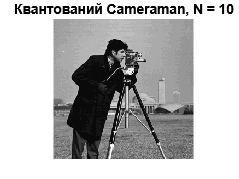

% Відображення квантованих вихідних зображень
figure, imshow(cameramanQuantSmall, [0 255]), title(['Квантований Cameraman, N = ', num2str(N_img_small)]);

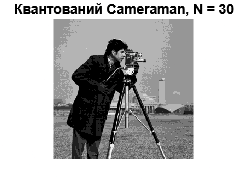

figure, imshow(cameramanQuantMedium, [0 255]), title(['Квантований Cameraman, N = ', num2str(N_img_medium)]);

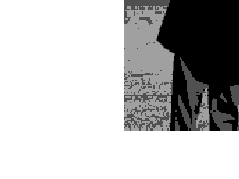

figure, imshow(cameramanQuantLarge, [0 255]), title(['Квантований Cameraman, N = ', num2str(N_img_large)]);

% Обчислення ДКП від квантованих вихідних зображень
dctCameramanImgQuantSmall = dct2(cameramanQuantSmall);
dctCameramanImgQuantMedium = dct2(cameramanQuantMedium);
dctCameramanImgQuantLarge = dct2(cameramanQuantLarge);

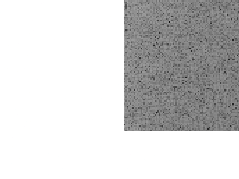

% Відображення результатів ДКП від квантованих вихідних зображень
figure, imshow(log(abs(dctCameramanImgQuantSmall)), []), title(['ДКП від квантованого вихідного зображення, N = ', num2str(N_img_small)]);

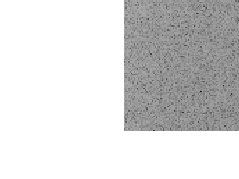

figure, imshow(log(abs(dctCameramanImgQuantMedium)), []), title(['ДКП від квантованого вихідного зображення, N = ', num2str(N_img_medium)]);

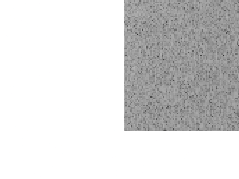

figure, imshow(log(abs(dctCameramanImgQuantLarge)), []), title(['ДКП від квантованого вихідного зображення, N = ', num2str(N_img_large)]);

### 9.3 Порівняння з квантуванням вихідного зображення:

*Квантування вихідного зображення дає суттєво гірші результати:*

*При однаковому кроці квантування N візуальна якість значно гірша*

*На квантованому вихідному зображенні з'являються чіткі "сходинки" яскравості*

*Кількість ненульових коефіцієнтів ДКП після квантування вихідного зображення залишається високою, що не забезпечує ефективного стиснення*

*ДКП від квантованого вихідного зображення містить багато високочастотних компонентів, які з'являються через різкі переходи між квантованими рівнями*

### 9.1 Чи можливо добитися аналогічної мети й результату, квантуючи вихідне зображення, а не коефіцієнти його ДКП?

*Ні*

## 10. Які недоліки ви бачите в стисненні зображень із використанням його ДКП і квантування коефіцієнтів ДКП?

*При сильному квантуванні (великих N) з'являються характерні блочні артефакти*

*Можлива втрата важливих дрібних деталей зображення*

*Метод має фіксовану ступінь стиснення для всього зображення, не враховуючи локальні особливості різних областей*

*Артефакти стають особливо помітними на чітких границях об'єктів*